%% 3. A script file for check the corectness of the implementation and the evaluation of the results
% Load the point of the stereo image (Mire)
P1M_1 = load ('Mire/Mire1.points');
P2M_2 = load ('Mire/Mire2.points');

% Load the poit of the stereo image (Rubik)
P1R_1 = load ('Rubik/Rubik1.points');
P2R_2 = load ('Rubik/Rubik2.points');

row_numberM = size(P1M_1, 1);
ones_columnM = ones(row_numberM, 1);

% convert in homogeneous cordinate
PM1 = [P1M_1, ones_columnM];
PM1 = PM1';
% want to consider a row vector

PM2 = [P2M_2, ones_columnM];
PM2 = PM2';

row_numberR = size(P1R_1, 1);
ones_columnR = ones(row_numberR, 1);

% convert in homogeneous cordinate
PR1 = [P1R_1, ones_columnR];
PR1 = PR1';
% want to consider a row vector

PR2 = [P2R_2, ones_columnR];
PR2 = PR2';

% Call the function for calculate the normalized fondamental matrix 
FM = EightPointsAlgorithm(PM1', PM2,row_numberM);
FM_N = EightPointsAlgorithmN(PM1, PM2); % Pass P1 transpose for the produìct inside the function 

FR = EightPointsAlgorithm(PR1', PR2,row_numberR);
FR_N = EightPointsAlgorithmN(PR1, PR2);
% evaluate the results of f:
% chceck the epipolar constraints x'Fx = 0,  check for every point
for i = 1:1:row_numberM
    % evaluate the epipolar constraint for not normalized point 
    result(i) = PM2(:,i)' * FM * PM1(:,i);
    % evaluate the epipolar constraint for not normalized point
    result_N(i) = PM2(:,i)' * FM_N * PM1(:,i);
end
rangoFM = rank(FM_N);

for i = 1:1:row_numberR
    % evaluate the epipolar constraint for not normalized point 
    result(i) = PR2(:,i)' * FR * PR1(:,i);
    % evaluate the epipolar constraint for not normalized point
    result_N(i) = PR2(:,i)' * FR_N * PR1(:,i);
end
rangoFR = rank(FR_N);
imgM1 = imread('Mire/Mire1.pgm');

imgM2 = imread('Mire/Mire2.pgm');

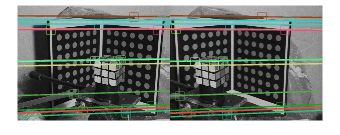

imgR1 = imread ('Rubik/Rubik1.pgm');
imgR2 = imread ('Rubik/Rubik2.pgm');

% this function allows me to visualize the epipolar line give the two
% images with the two pair of point
visualizeEpipolarLines( imgM1, imgM2, FM_N, P1M_1, P2M_2);
figure;

visualizeEpipolarLines( imgR1, imgR2, FR_N, P1R_1, P2R_2);

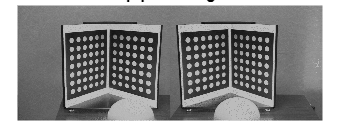

% looking for the epipole
%needs to applicate the decomposition svd to F matrix F = UWV' and select
%the last columns of U and V

[U W V] = svd (FM_N);
last_col_U = U(1:2,end); % epipole left image
last_col_V = V(1:2,end); % epipole right image
figure;
Im = [imgM1 imgM2];
imshow(Im);
hold on
plot(last_col_U(1),last_col_U(2),'r*','Color', 'red','LineWidth', 8);
xv = [1:size(imgM1,2)];
plot(xv + last_col_V(1),last_col_V(2),'s', 'Color', [1,0,0], 'LineWidth', 8);
hold off
title ("Epipole image");

Part 2

Features matched: 294


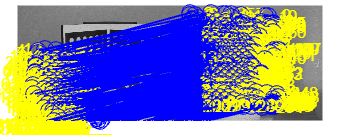

% imgRubik1 = imread('Rubik/Rubik1.pgm');
% imgRubik2 = imread('Rubik/Rubik2.pgm');

%list_ncc = findMatches(imgRubik1, imgRubik2, 'NCC');
%list_sift = findMatches(imgRubik1, imgRubik2, 'SIFT');

%figure, show_matches(imgRubik1, imgRubik2, list_ncc, 0, 10);
%figure, show_matches(imgRubik1, imgRubik2, list_sift, 1, 11);

list_sift = findMatches(imgM1, imgM2, 'SIFT');

%figure, show_matches(imgRubik1, imgRubik2, list_ncc, 0, 10);
figure, show_matches(imgM1, imgM2, list_sift, 1, 11), title("show matches");

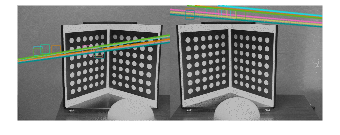


% Find the correspondence point extimated with image matching
A_1 = [list_sift(:, 1:2)];
B_1 = [list_sift(:, 3:4)];

row_number = size(A_1, 1);
ones_columnM = ones(row_number, 1);

% convert in homogeneous coordinate and transpose, need to have every point in each column 
A = [A_1, ones_columnM];
A = A';
% want to consider a row vector
B = [B_1, ones_columnM];
B = B';

[bestF, consensus, outliers] = ransacF(A, B, 0.008);
% Points of first image 
A_2 = consensus(1:2, :)';
B_2 = consensus(4:5, :)';
visualizeEpipolarLines(imgM1, imgM2, bestF, A_2, B_2);


% [bestF, consensus, outliers] = ransacF(A, B, 0.01);
% visualizeEpipolarLines(imgM1, imgM2, bestF, A_1, B_1);







